# Equilibria in Truss Beams

Instructions are in the task pane to the left. Complete and submit each task one at a time.

A = [-sind(30) -sind(30) 0 0 0 0 0 0 0;...
    -cosd(30) cosd(30) 0 0 0 0 0 0 0; ...
    sind(30) 0 0 -sind(60) -sind(60) 0 0 0 0;...
    cosd(30) 0 1 -cosd(60) cosd(60) 0 0 0 0;...
    0 sind(30) 0 0 0 -sind(60) -sind(60) 0 0;...
    0 -cosd(30) -1 0 0 -cosd(60) cosd(60) 0 0;...
    0 0 0 0 sind(60) sind(60) 0 0 0;...
    0 0 0 0 -cosd(60) cosd(60) 0 -1 1;...
    0 0 0 0 0 0 -cosd(60) 0 -1]

A =    -0.5000   -0.5000         0         0         0         0         0         0         0
   -0.8660    0.8660         0         0         0         0         0         0         0
    0.5000         0         0   -0.8660   -0.8660         0         0         0         0
    0.8660         0    1.0000   -0.5000    0.5000         0         0         0         0
         0    0.5000         0         0         0   -0.8660   -0.8660         0         0
         0   -0.8660   -1.0000         0         0   -0.5000    0.5000         0         0
         0         0         0         0    0.8660    0.8660         0         0         0
         0         0         0         0   -0.5000    0.5000         0   -1.0000    1.0000
         0         0         0         0         0         0   -0.5000         0   -1.0000


## Task 1

A 9x9 matrix of force coefficients has been created for you.

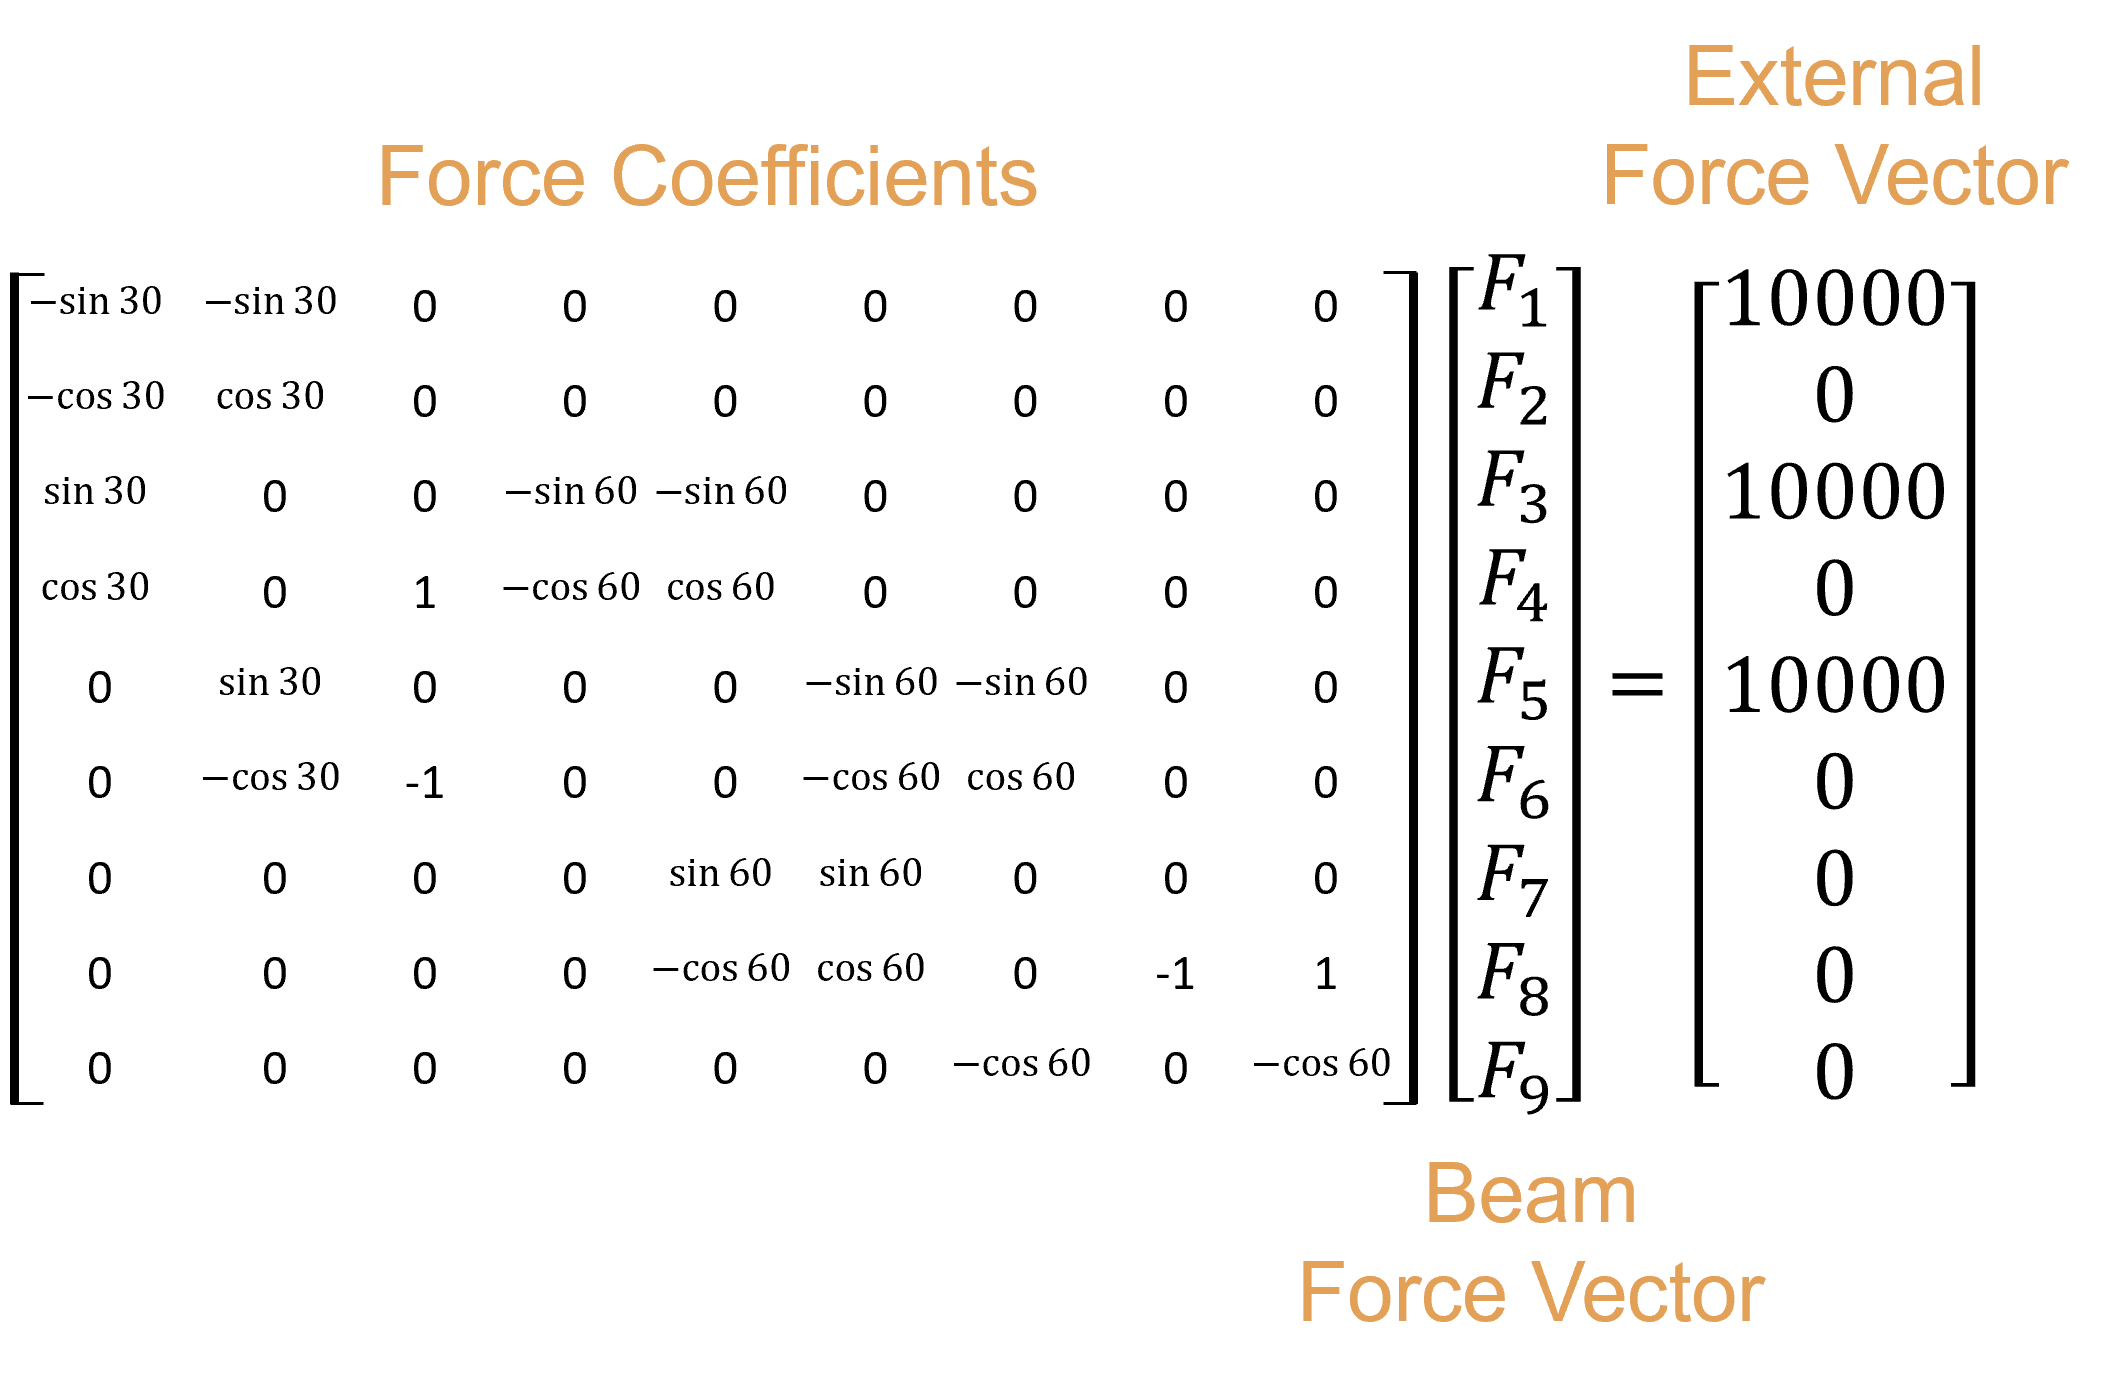

b = [10000; 0; 10000; 0; 10000; 0; 0; 0; 0]

b =        10000
           0
       10000
           0
       10000
           0
           0
           0
           0


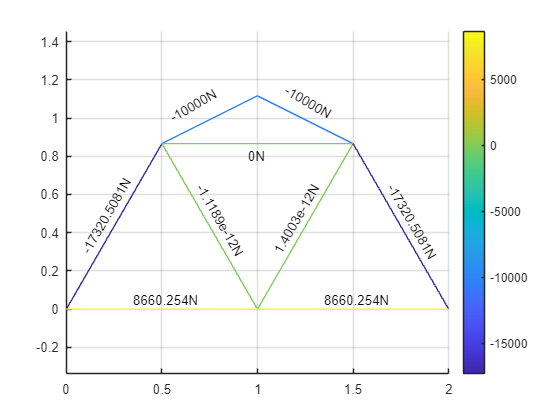

f = A\b;
plotTruss(f)

function plotTruss(f)
    %Joint Locations
    x = [0 0.5 1 1 1.5 2];
    y = [0 sind(60) (sind(60)+0.5*sind(30)) 0 sind(60) 0];
    
    %Rescale forces to be between 1 and 255
    fScale = round(rescale(f,0,255))+1;
    cmap = colormap("parula");
    
    %Plot and label beams
    hold on
    grid on
    line([x(2) x(3)],[y(2) y(3)],"Color",cmap(fScale(1),:))
    text(0.55,1.0,num2str(f(1))+"N","rotation",30)
    line([x(4) x(5)],[y(3) y(2)],"Color",cmap(fScale(2),:))
    text(1.15,1.15,num2str(f(2))+"N","rotation",-30)
    line([x(2) x(5)],[y(2) y(2)],"Color",cmap(fScale(3),:))
    text(0.95,0.8,num2str(f(3))+"N")
    line([x(1) x(2)],[y(1) y(2)],"Color",cmap(fScale(4),:))
    text(0.1,0.3,num2str(f(4))+"N","rotation",60)
    line([x(2) x(3)],[y(2) y(1)],"Color",cmap(fScale(5),:))
    text(0.7,0.65,num2str(f(5))+"N","rotation",-60)
    line([x(4) x(5)],[y(4) y(5)],"Color",cmap(fScale(6),:))
    text(1.1,0.3,num2str(f(6))+"N","rotation",60)
    line([x(5) x(6)],[y(5) y(6)],"Color",cmap(fScale(7),:))
    text(1.7,0.65,num2str(f(7))+"N","rotation",-60)
    line([x(1) x(3)],[y(1) y(1)],"Color",cmap(fScale(8),:))
    text(0.35,0.05,num2str(f(8))+"N")
    line([x(3) x(6)],[y(1) y(1)],"Color",cmap(fScale(9),:))
    text(1.35,0.05,num2str(f(9))+"N")
    hold off
    colorbar
    clim([min(f) max(f)])
    axis equal
end